# A

s = tf('s');
G = [10*(s+1)/(s^2+0.2*s+100),1/(s+5);(s+2)/(s^2+0.1*s+10),5*(s+1)/((s+2)*(s+3))]

G =
 
  From input 1 to output...
           10 s + 10
   1:  -----------------
       s^2 + 0.2 s + 100
 
            s + 2
   2:  ----------------
       s^2 + 0.1 s + 10
 
  From input 2 to output...
         1
   1:  -----
       s + 5
 
          5 s + 5
   2:  -------------
       s^2 + 5 s + 6
 
Continuous-time transfer function.



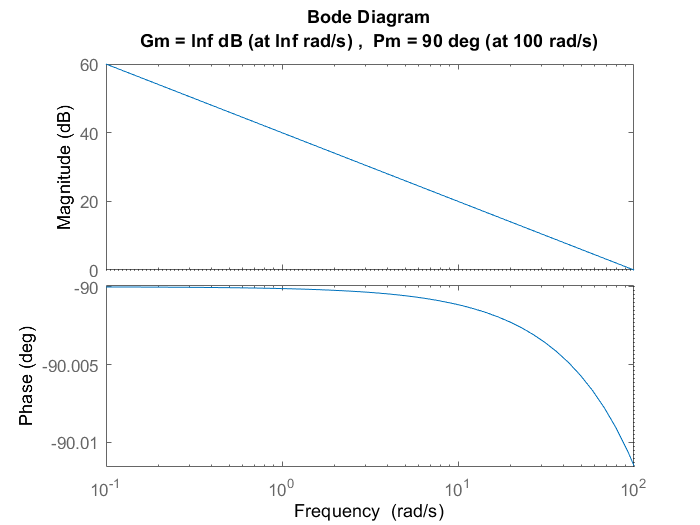

tau = 500000;
% High frequency pole added to the inverse
G_hat = inv(G)/(1+s/tau);

L = [100/s 0;0 100/s];
K = L*G_hat;

% minimum realization
l = minreal(G*K);
L11 = l(1,1);
margin(L11)

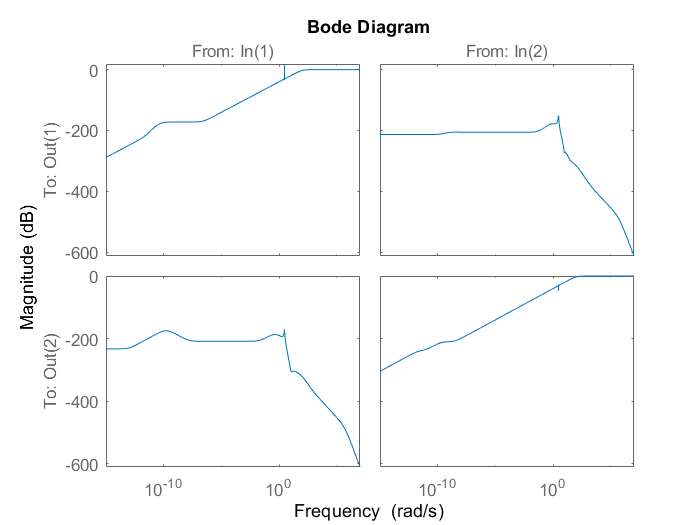


S = inv(eye(2)+l);
bodemag(S)

# B

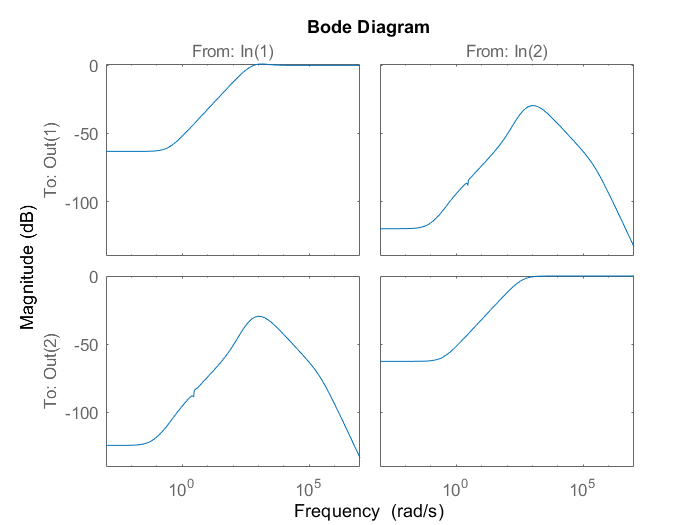

BW = 100;
Wu = [1/100 0;0 1/100];

% A while loop to maximize the bandwidth
while 1
    Wp = makeweight(1000,BW,1/2)*eye(2);
    Wt = makeweight(1/1.5,3*BW,1000)*eye(2);
    [K,CL,GAM,info] = mixsyn(G,Wp,Wu,Wt);
    if GAM>1
        break
    end
    BW = BW + 5;
end

% Computing the Sensitivity, Complementary Sensitivity, and the controller weight compensator
L = G*K;
T = feedback(L,eye(2));
S = eye(2) - T;

bodemag(S)

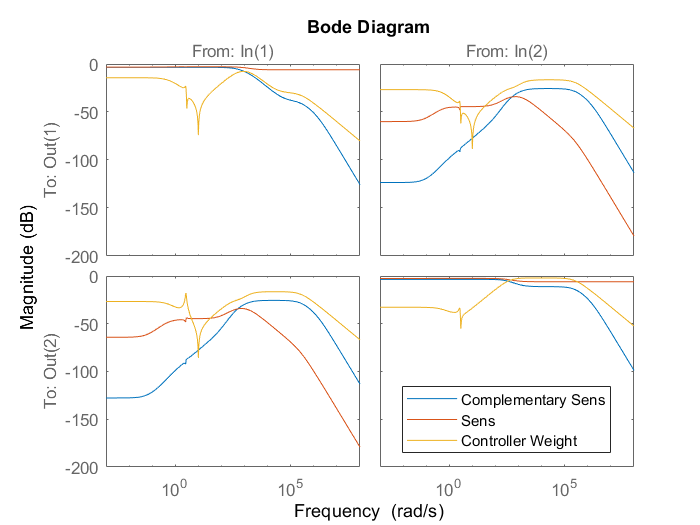

R = K*S;
bodemag(Wt*T,Wp*S,Wu*R)
legend('Complementary Sens','Sens','Controller Weight',"Location","best")